## **Viviana Tran Midterm F2022 E7**

clear all
%Problem 1 create an M*M matrix in ascending order then re-arrange it in a
%spiral pattern
clc
%generating a random 11*11 array 
generatedArray= randi(100,11) 

generatedArray =     66    53    12    79    60    88    20    73    87     6    92
    91    26    32    12    45     6    43    10     6    63    79
   100    97    23    98     4    22    17    88    82    80    30
    66    55    66    85    52    46    76     2    53    70    16
    11     4     7     6    41    96    37    30    70    35    85
     4    70    28    47    11    80    95    18    22    95    79
    62    52    29    33    46    46     2    93    55    53    28
    57     6    89    64    46    34    83     7    71    96    23
    97    90    45    24    56     6    63    59    96     8    33
    75    34    76    58    81    75    54    64    45    21    83


generatedArray = reshape(generatedArray, [1, length(generatedArray)^2]);
%sorting the matrix in ascending order (square matrix) 
organizedArray = reshape(myQuickSort(generatedArray), [sqrt(length(generatedArray)), sqrt(length(generatedArray))])'

organizedArray =      2     2     4     4     4     6     6     6     6     6     6
     7     7     8     9    10    11    11    12    12    16    17
    18    20    21    22    22    23    23    23    24    26    28
    28    29    30    30    32    33    33    34    34    35    37
    41    43    45    45    45    46    46    46    46    47    51
    52    52    53    53    53    54    55    55    56    57    58
    59    60    61    61    62    63    63    64    64    66    66
    66    66    66    67    70    70    70    71    71    73    75
    75    76    76    78    79    79    79    80    80    81    82
    83    83    83    85    85    87    88    88    89    90    91


%sorting within a spiral
A = mySpiralSort(organizedArray)

A =     83    83    82    81    80    80    79    79    79    78    76
    83    57    56    55    55    54    53    53    53    52    76
    85    58    30    30    29    28    28    26    24    52    75
    85    59    32    11    10     9     8     7    23    51    75
    87    60    33    11     4     4     4     7    23    47    73
    88    61    33    12     6     2     2     6    23    46    71
    88    61    34    12     6     6     6     6    22    46    71
    89    62    34    16    17    18    20    21    22    46    70
    90    63    35    37    41    43    45    45    45    46    70
    91    63    64    64    66    66    66    66    66    67    70


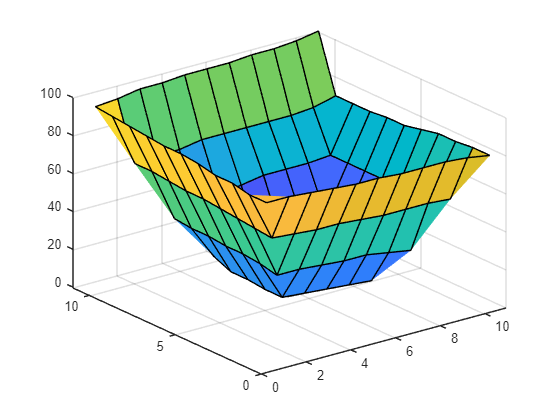

surf(A)

**Problem One Discussion:  **

In order to solve this problem, I had to first create a random array, reorganize the random array into a one row, multiple column array, pivot sort the random array, reorganize the array into the square matrix, transpose the matrix, and read the matrix backwards in order to get the largest number to the smallest number. There were multiple approaches to solving this problem. For example, I used a while loop to denote each direction the numbers could go but another approach is utilizing recursion. I decided to use the first approach even though the time complexity is O(n^2) (because it loops through the rows and the columns) because it was more simple to see exactly the directions the spiral is going. Furthermore, (when working from the outside in) the right and top row have to be shifted in one extra, which was more easily solved via while loops.

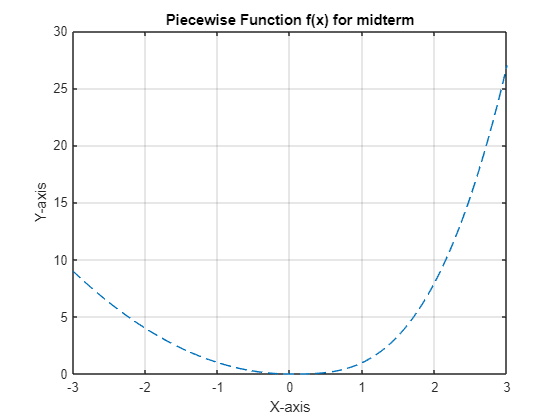

clear all
%Problem 2 plot the function, calculate the right, left, and mid riemann
%sum, and find the error compared to the actual integral
%analytically, the definite integral of f(x) from -3 to 3 is 29.25
clc

%graphing what the piecewise function looks like
x1= linspace(-3,0,1000);
eq1 = x1.^2;

x2= linspace(0,3,1000);
eq2 = x2.^3;

figure
x= [x1 x2];
y = [eq1 eq2];
plot(x,y,'--');
xlabel('X-axis')
ylabel('Y-axis')
title('Piecewise Function f(x) for midterm')
grid on



%calculuating the riemann sums and the respective errors compared to the
%integral
n=100

n = 100

leftRiemannSum = leftRiemann(-3,3,n)

leftRiemannSum = 28.7199

e= (error(leftRiemannSum))

e = 0.0181

rightRiemannSum = rightRiemann(-3,3,n)

rightRiemannSum = 29.7999

e= (error(rightRiemannSum))

e = 0.0188

midRiemannSum = midRiemann(-3,3,n)

midRiemannSum = 29.2451

e= (error(midRiemannSum))

e = 1.6923e-04


n=1000

n = 1000

leftRiemannSum = leftRiemann(-3,3,n)

leftRiemannSum = 29.1961

e= (error(leftRiemannSum))

e = 0.0018

rightRiemannSum = rightRiemann(-3,3,n)

rightRiemannSum = 29.3041

e= (error(rightRiemannSum))

e = 0.0018

midRiemannSum = midRiemann(-3,3,n)

midRiemannSum = 29.2500

e= (error(midRiemannSum))

e = 1.6923e-06

**Problem Two Discussion:**

To calculate the right riemann sum, left riemann sum, the midpoint riemann sum, and their respective errors, I created four functions. Since it needed to be tested with different test cases, a function was the most useful so that a repeated task can occur. The analytical solution to the area underneath the curve was 29.25 which (shown by the error values where the error values when n = 100 range from 1.6923e-04 - 0.0188 while when n =1000 produces a range of 1.6905e-06- 0.0018) was better obtained when n = 1000. The more rectangles the area is split into better approximates the height of the function at that given point, allowing for the summation of these areas to be more precised. Since the function is decreasing until 0, a left riemann sum produces an overestimate while a right riemann sum produces an underestimate. Since the function is increasing after 0, a left riemann sum produces an underestimate while a right riemann sum produces an overestimate. This is seen in the errors in which the left riemann sum and right riemann sum produce greater errors than the midriemann sum.

clear all
%Problem 3 write a binary search code that finds a target with multiple appearances,
%return the indices of the target number in the original array
%test case
A = [ 2 4 0 1 1 2 3 -3 4 -4 4 5 2 8 1 10 10 1]

A =      2     4     0     1     1     2     3    -3     4    -4     4     5     2     8     1    10    10     1


[originalindex] =myBinarySearch(A,1)

originalindex =      4     5    15    18


**Problem Three Discussion:**

In this problem, I was asked to utilize binary search but rather than return the indexes of the sorted array, I had to return the indexes of the unsorted array. To solve this problem, I had to find a way to organize the array in such a way that the original indexes were a property or had a similarity to the target number indexes of the sorted array. Initally, I thought of utilizing a struct array so that the original indexes were fields of the target number. However, since the binary code shown in lecture implemented the sorted array rather than the unsorted array I realized that something must be done in the sorting step rather than the search step. With this in mind, I developed a separate array of integers that was sorted in tandem with the unsorted array. I used a bubble sort so that the elements of the integer array can be moved with the element values of the unsorted array. Therefore, the binary search indexes for the target numbers matched those of the original index array and I could splice the original index array at the same place as the binary search indexes to get the desired result.

clear all
%Problem 4 write a recursive function to count the steps to get to 1 via the collatz
%conjecture
k=0;
%test case
n=1234567890

n = 1.2346e+09

k=myRecursive(n)

k = 351

**Problem Four Discussion:**

The collatz conjecture states that all positive integers will ultimately go to one. Thus, we can use n (the positive integer) as a factor of the base case. When n equals 1 is when the inputed integer has gone through as many steps as it needed to get to one. If the integer is an even number, the recursive function is called such that the input is half of the previous integer. However, if it is odd the "else" recursive function is called. k represents the number of times it took to get to 1 and each time the myRecursive is called the k is increased by the steps it took. If the number is an odd number, 2 is added to k since the number is both multiplied by 3 added by 1 and divided by 2 to speed up the calculation process. 

*Functions for Question One:*

function [organizedArray] = myQuickSort (generatedArray)
%quick sort function with time complexity O(nlogn)
a = length(generatedArray);
if a<2
    %produces a base case for the recursive function
    organizedArray=generatedArray;
    return
end
pivotIndex= randi(a,1); 
pivot = generatedArray(pivotIndex);
smaller = [];
equal = [];
larger = [];

for i = 1:a
    if generatedArray(i)<pivot
        smaller = [smaller, generatedArray(i)];
    elseif generatedArray(i)>pivot
        larger = [larger, generatedArray(i)];
    elseif generatedArray(i)==pivot
        equal = [equal,generatedArray(i)];
    end
end
organizedArray = [myQuickSort(smaller),equal,myQuickSort(larger)];
end




function [spiral] = mySpiralSort (organizedArray)
[rows,columns] = size(organizedArray);
%transpose the organized array so that it is read in ascending order from 1
%to length of array
organizedArray= organizedArray';
spiral = zeros(rows,columns);
top = 1;
left = 1;
%i allows the code to read from the end to the start (biggest number to the
%inside number)
i=rows*columns;

j=0;
h=0;


while i>0

    while j<columns-h
        %columns to the left
        %as j increases, the columns move towards the left, filling the
        %bottom rows
        spiral(rows,columns-j) = organizedArray(i);
        i=i-1;
        j=j+1;
    end
rows=rows-1;
%because bottom row is filled, the rows decrease by one
j=0;

while j<rows-h
    %up on the left side
    %left starts at column one since columns will give the right side
    spiral (rows-j,left) = organizedArray(i);
    i=i-1;
    j=j+1;
end
left =left+ 1;
%left increases one so that the spiral goes inwards

j=0;
while j<columns-h-1
    %top to the right 
    %have to reduce by one since the column is now filled on both sides
    spiral (top,left+j) = organizedArray(i);
    i=i-1;
    j=j+1;
end
top = top+1;
j=0;

while j<rows-h-1
    %down on the right side
    %have to reduce by one since the row is now filled on top and bottom
    spiral (top+j, columns)= organizedArray(i);
    i=i-1;
    j=j+1;
    
end
columns = columns - 1;
j=0;
h=h+1;

end
end



*Functions for Questions Two:*


function areaOfLR = leftRiemann (a,b,n)
changeOfX = (b-a)/n;
xi=[];
i=1;
j=1;
areaOfLR=0;
while j <= (n)
    %creates an array of all x values
    xi(i) = a;
    i=i+1;
    j=j+1;
    a=a+changeOfX;
end
for i=1:length(xi)
    %since it is a left riemann sum, takes the number from the left side to
    %1 less than the last number
    if xi(i)<0
    areaOfLR = areaOfLR + changeOfX * ((xi(i))^2); 
    else
    areaOfLR = areaOfLR + changeOfX * ((xi(i))^3); 
    end
end
end




function areaOfRR = rightRiemann (a,b,n)
changeOfX = (b-a)/n;
a=a+changeOfX;
xi=[];
i=1;
j=1;
areaOfRR=0;
while j <= n
    xi(i) = a;
    i=i+1;
    j=j+1;
    a=a+changeOfX;
end
for i=1:length(xi)
    %since it is a right riemann sum, takes the number from the right side to
    %the last number
    if xi(i)<0
        
    areaOfRR = areaOfRR + changeOfX * (xi(i))^2;
    else
    areaOfRR = areaOfRR + changeOfX * (xi(i))^3; 
    end
end
end



function areaOfMR = midRiemann (a,b,n)
changeOfX = (b-a)/n;
xi=[];
i=1;
j=1;
areaOfMR=0;
while j <= (n+1)
    xi(i) = a;
    i=i+1;
    j=j+1;
    a=a+changeOfX;
end

i=1;
while length(xi)>1
    %adds two numbers side by side and then finds the midpoint to calculate
    %riemann sum, stops when theere is only one element left in array.
    if (xi(i)+xi(i+1))/2<0
    areaOfMR = areaOfMR + changeOfX * (((xi(i)+xi(i+1))/2)^2);
    else
    areaOfMR = areaOfMR + changeOfX * (((xi(i)+xi(i+1))/2)^3);
    end
    xi = xi(i+1:end);
    

end
end

function e = error (sum)
%compares the riemann sum to the integral
e= abs((sum- 29.25)/29.25); 
end




*Functions for Question Three:*

function [originalindex] = myBinarySearch(array,num)
    indices = 1:size(array,2);
    [array,indices] = Bubble(array,indices);
    function [array,indices] = Bubble(array,indices)
%gives the sorted array with respective indexes from original array
    n=size(array,2);
    for i= 1:n
        for j=1:(n-1)
            %swaps so that the values of the array is in order and the
            %respective indexes correlate with this array
            if array(j)>array(j+1)
                temp = array(j);
                array(j)=array(j+1);
                array(j+1)=temp;
                tempor = indices(j);
                indices(j)=indices(j+1);
                indices(j+1)= tempor;
            end
        end    
    end
%originalindexes= binarySearch(array,num,indices)
    end

originalindex = indices;
n=length(array);
left = 1;
right = n;
flag = 0;
index =[];

while left <= right
    mid = ceil((left + right) / 2);
    
    if array(mid) == num
        index = [index,mid];
        flag = 1;
        %
        % Find the repeated number in - side
        lmid=mid-1;
        while array(lmid) == num
            index = [index, lmid];
            lmid=lmid-1;
        end
        % Find the repeated number in + side
        rmid=mid+1;
        while array(rmid) == num
            index = [index, rmid];
            rmid=rmid+1;
        end
        index = myQuickSort(index);
        break
    else if array(mid) > num
        right = mid - 1;
        else
            left = mid + 1;
        end
    end

end

if flag == 0
    index = [index,-1];
    fprintf('This guy is not here !');
end
%returns the array for the original indexes, splicing where the target
%numbers are 
    originalindex = originalindex(index(1):index(length(index)));
end

*Functions for Question Four:*

function k = myRecursive(n)
%k counts the steps of the recursive
if n == 1
    %base case
    k=0;
    return
elseif n==3
    %base case
    k=k+7;
    return
elseif mod(n,2) == 0
    %checks if the number is odd or even
    k = 1+ myRecursive(n/2);
else
    k = 2 +myRecursive ((3*n+1)/2);
end
end




**Short Midterm Exam Report**

The outputs of the 4 functions can be found on the right.  Throughout the process of coding these functions to get the desired output, I had to debug as I went. I coded the four problems separately in order to breakdown the large problems into smaller ones. Furthermore, I created a flow chart to develop the code and then I tested an adjusted the code until needed. In regards to accuracy, I developed test cases in which I knew what the solutions would be. I tested a series of these test cases until I knew that it would be correct.